data = readtable('proc_data_row.csv','TextType','string');
head(data)

ans = 8×5 table
    Var1           no           month    day                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                            

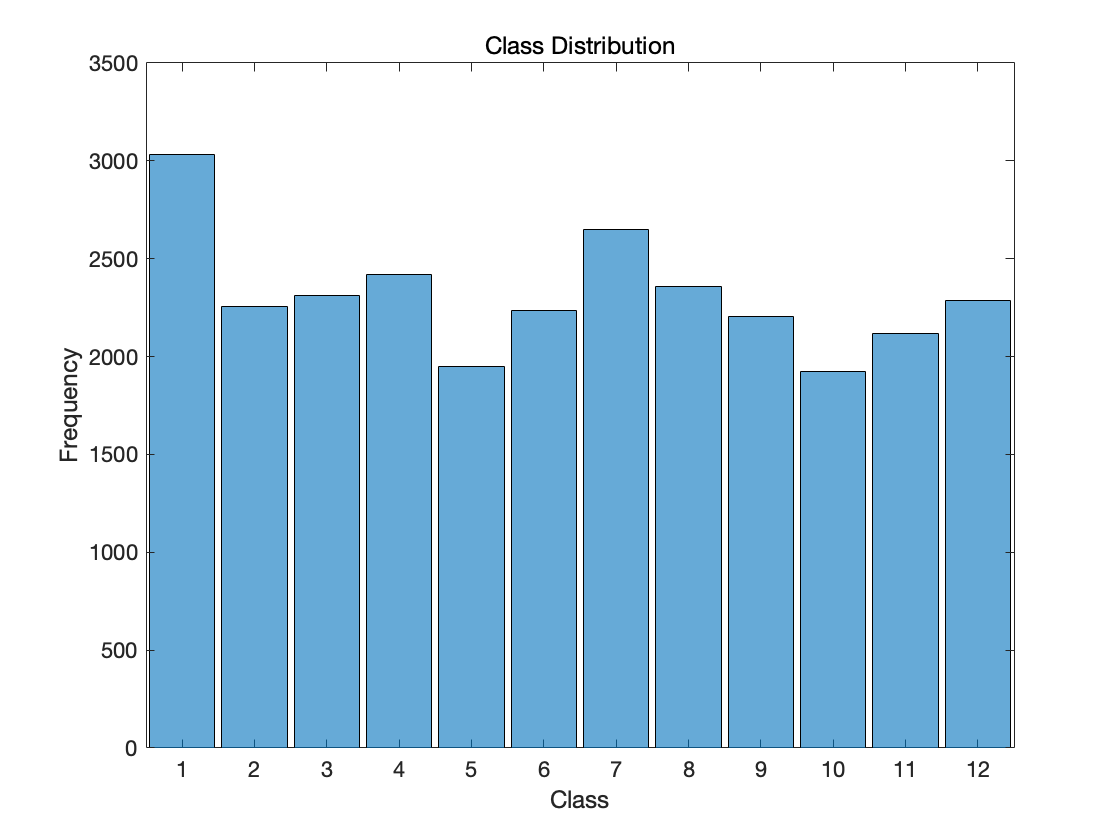

% 删除空行
idx = strlength(data.content) == 0;
data(idx,:) = [];
% 将event_type列中的标签转换为标签，
% 使用直方图显示。
data.month = categorical(data.month);
figure
h = histogram(data.month);
xlabel("Class")
ylabel("Frequency")
title("Class Distribution")

% 从直方图中获取类的频率计数及其名称。
classCounts = h.BinCounts

classCounts =         3032        2255        2312        2418        1947        2234        2649        2360        2206        1924        2118        2284


classNames = h.Categories

classNames = 1×12 cell 数组
    {'1'}    {'2'}    {'3'}    {'4'}    {'5'}    {'6'}    {'7'}    {'8'}    {'9'}    {'10'}    {'11'}    {'12'}


% 查找并删除少于30个观测值的类。
idxLowCounts = classCounts < 30;
infrequentClasses = classNames(idxLowCounts);
idxInfrequent = ismember(data.content,infrequentClasses);
data(idxInfrequent,:) = []

data = 27739×5 table
    Var1           no           month    day                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       

% 文本清洗（预处理）。
% 使用函数preprocessWeatherNarratives对文本进行预处理
documents = preprocessRMRB(data.content);
documents(1:5)

ans =   5×1 tokenizedDocument:

     259 tokens: 百姓 人民 论坛 这代 百姓 农民 社会 道路 不能 全面 小康 大家 一起 参加 国政 经济 习近 总书 自己 陕北 黄土 贫苦 日子 岁月 百姓 发人 思考 过去 中国 巨轮 风雨 无阻 忧乐 百姓 政府 兹在 中心 议题 2019 农村 贫困 人口 减少 1109 支配 百姓 书写 温度 民生 故事 疫情 108 老人 出生 30 婴儿 患者 百姓 震撼 世界 生命 亿万 人民 满满 获得 稳稳 幸福 安全 人民 根本 宗旨 人民 中心 发展 思想 百姓 就是 百姓 时刻 心中 百姓 农功 思之 农业 社会 中国 传统 政治 思想 对于 强调 用心 土地 需要 日夜 才能 万斛 仓廪 为政 如此 朝暮 于民 事事 为民 才能 做到 为官 一任 一方 对于 产党 什么 百姓 百姓 什么 人民 心中 最高 位置 就是 保持 时时 放心 怀有 百姓 实际 人民 人民 满意 肚子 净颗 细粮 细粮 经常 挑着 扁担 习近 总书 谈起 几个 说明 这样 观点 保障 改善 民生 终点 连续 不断 起点 问题 全面 小康 胜利 放心 健康 人民 美好 生活 不断 攀升 需要 民生 改善 进一 百姓 百姓 具体 百姓 日子 幸福 百姓 实实 良心 需用 真心 需见 决战 决胜 剩下 硬骨 叠加 疫情 难上 集中 精力 以保 促稳 稳中 发展 需要 民生 需要 就业 900 减税 费约 5000 亿元 不足 农民 纳入 常住 保障 新建 标准 农田 8000 今年 政府 工作 报告 系列 民生 举措 见证 大国 民生 牵挂 激励 级党 政府 民生 工作 真正 百姓 变成 实际 天下 天下 天下 天下 赢得 疫情 胜利 还是 如期 全面 小康 社会 根本 动力 人民 百姓 民心 民力 亿万 人民 劲往 一定 战胜 一切 艰难 险阻 书写 无愧 时代 无愧 历史
    1108 tokens: 推动 社会 核心 价值 家庭 落地 以来 习近 总书 国家 发展 全局 促进 全面 发展 家庭 家教 发表 系列 重要 讲话 强调 家庭 家教 家

bag = bagOfWords(documents)

bag =   bagOfWords - 属性:

          Counts: [27739×109773 double]
      Vocabulary: [1×109773 string]
        NumWords: 109773
    NumDocuments: 27739


 bag = removeInfrequentWords(bag,2); % remove infrequent words
[bag,~] = removeEmptyDocuments(bag); % remove empty doc
bag

bag =   bagOfWords - 属性:

          Counts: [27731×57276 double]
      Vocabulary: [1×57276 string]
        NumWords: 57276
    NumDocuments: 27731


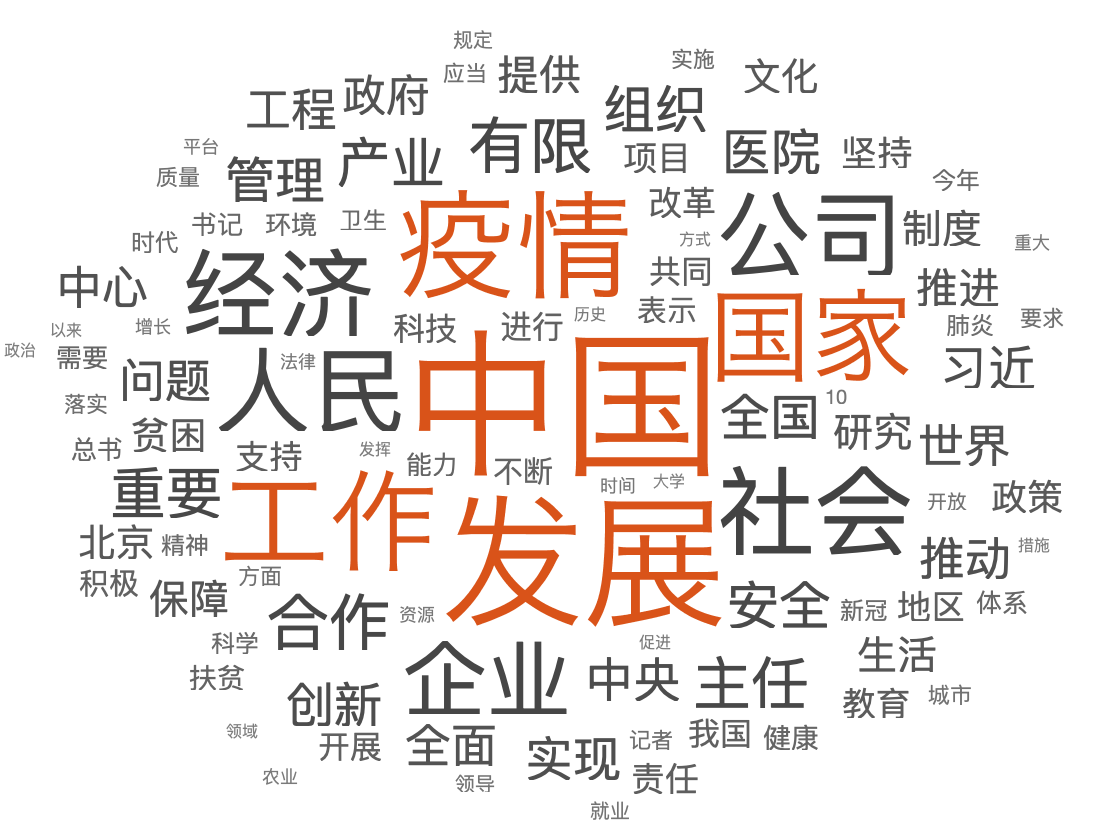

ans =   WordCloudChart - 属性:

           WordData: [1×57276 string]
           SizeData: [1×57276 double]
    MaxDisplayWords: 100

  显示 所有属性


figure
wordcloud(bag)